**Simple Linear Regression**

clc
clear 
close all; 

load carsmall

mdl = fitlm(Weight,Horsepower) 

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)     -35.593       8.6563    -4.1118    8.2242e-05
    x1             0.049022    0.0027764     17.657     4.646e-32


Number of observations: 99, Error degrees of freedom: 97
Root Mean Squared Error: 22.3
R-squared: 0.763,  Adjusted R-Squared: 0.76
F-statistic vs. constant model: 312, p-value = 4.65e-32

Weight = predictor (constant)

Horsepower = dependent variable 

**Intercept** = coefficent b (skæring med yakse) # statistisk signigikant 

**x1** = coefficient a (hældning) # statistisk signigikant (se pValue)

**Adjusted R-Squared** (Coefficent of determination) = 0.76

- R-squared value suggests that the model explains approximately 76% of the variability in the response variable MPG.

anova(mdl,'summary')

ans = 5×5 table
                       SumSq       DF      MeanSq        F        pValue  
                     __________    __    __________    ______    _________

    Total            2.0312e+05    98        2072.7                       
    Model            1.5492e+05     1    1.5492e+05    311.76    4.646e-32
    Residual              48202    97        496.93                       
    . Lack of fit         46732    91        513.54    2.0968       0.1761
    . Pure error         1469.5     6        244.92                       


**Model (regression) pValue** = 4.646e-32

- Sammenhængen er statistisk signifikant 

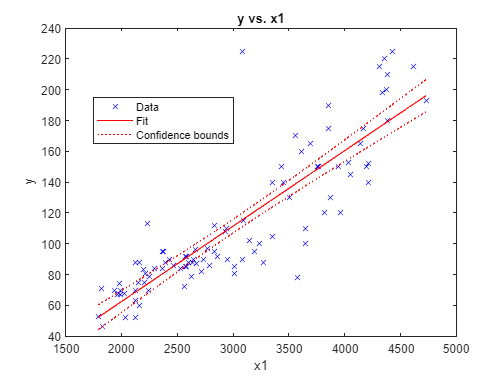

figure; 
plot(mdl)

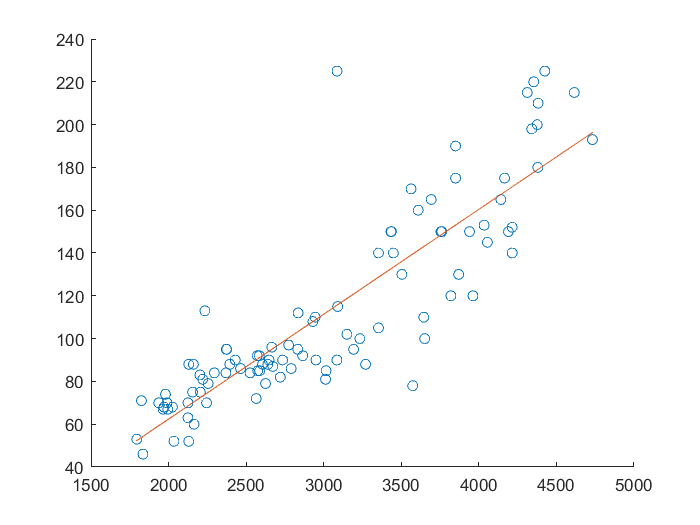


figure; hold on 
linearReg = @(x) x*0.049 - 35.593; 
scatter(Weight,Horsepower)
plot(Weight, linearReg(Weight))